load('Video8.mat');


mu = [ -0.0069    0.0092    0.0388];
std =  [1.6297    1.6028    1.6718];
for i = 1:3
pos.signals.values(:,i) = pos.signals.values(:,i)+mu(i)+std(i)*randn(size(pos.signals.values(:,i)));
end

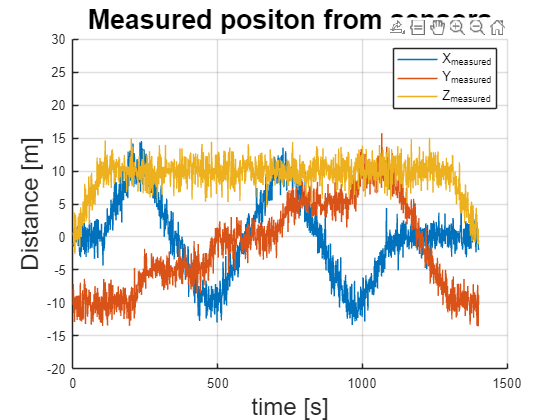

figure;
hold on;
for i = 1:3
plot(pos.signals.values(:,i));
end
legend('X_{measured}','Y_{measured}','Z_{measured}','FontSize',10);
ylabel('Distance [m]','FontSize',18);
xlabel('time [s]','FontSize',18);
title('Measured positon from sensors','FontSize',20);
ylim([-20 30]);
grid on

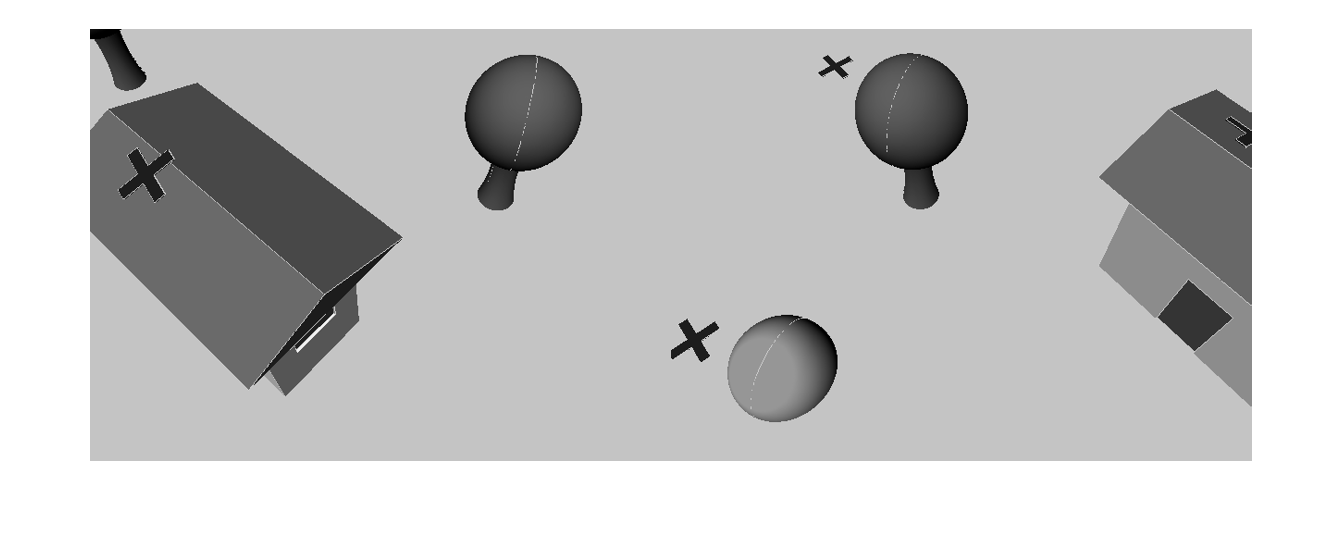

Index in position 4 exceeds array bounds. Index must not exceed 491.

d = 0.15;
Location = [];
i_list = [];
for idx = 2:size(vout_right,4)
    im_left = vout_left (:,:,:,idx);
    im_right = vout_right(:,:,:,idx);
    BW_left = createMaskBlue(im_left);
    BW_right = createMaskBlue(im_right);
    props_left = regionprops('table',BW_left,{'Centroid','Area'});
    props_right = regionprops('table',BW_right,{'Centroid','Area'});
    if (height(props_left)==0 || height(props_right) ==0) 
        continue;
    end
    i_list = [i_list;idx];
    psi_t = psi.signals.values(idx-1);
    phi_t = phi.signals.values(idx-1);
    
    Rot_C_W = roty(180)*rotz(psi_t*180/pi)*rotx(phi_t*180/pi);
    t_C_in_W_left = [pos.signals.values(idx-1,:,:)'] + Rot_C_W*[-d;0;0];
    t_C_in_W_right = [pos.signals.values(idx-1,:,:)'] + Rot_C_W*[d;0;0];
    t_W_in_C_left=-(Rot_C_W)'*t_C_in_W_left;
    t_W_in_C_right=-(Rot_C_W)'*t_C_in_W_right;
    intrinsic_matrix = [600 0 320; 0 600 240; 0 0 1];
    tform_left = rigidtform3d(Rot_C_W',t_W_in_C_left);
    tform_right = rigidtform3d(Rot_C_W',t_W_in_C_right);
    camera_left_params = cameraParameters(K=intrinsic_matrix);
    camera_right_params = cameraParameters(K=intrinsic_matrix);
    camera_left_params.ImageSize = [480 640];
    camera_right_params.ImageSize = [480 640];
    
    pose_cam_2 = rigidtform3d(eye(3),[-2*d;0;0]);
    stereo_params = stereoParameters(camera_left_params,camera_right_params,pose_cam_2);
    [cam_left_rect, cam_right_rect,reprojection_matrix] = ...
        rectifyStereoImages(im_left, im_right, stereo_params);
    cam_left_gray  = im2gray(cam_left_rect);
    cam_right_gray = im2gray(cam_right_rect);
        montage({cam_left_gray,cam_right_gray});    
    disparityMap = disparityBM(cam_left_gray, cam_right_gray,'DisparityRange',[0 128]);
    points3D = reconstructScene(disparityMap, reprojection_matrix);
    
    % Convert to meters and create a pointCloud object
    points3D = points3D./1;
    centroids = props_left.Centroid;
    centroids_idx = sub2ind(size(disparityMap),round(centroids(:,2)),round(centroids(:,1)));
    X = points3D(:, :, 1);
    Y = points3D(:, :, 2);
    Z = points3D(:, :, 3);
    centroids3D = [X(centroids_idx)'; Y(centroids_idx)'; Z(centroids_idx)'];
    e_C_to_W = [Rot_C_W t_C_in_W_left; 0 0 0 1];
    centroids3D_homo = [centroids3D;ones(1,size(centroids3D,2))];
    centroids_W = e_C_to_W*centroids3D_homo;
    Location = [Location;centroids_W(1:3,:)'];
end

Location = rmmissing(Location);

% for i = 1:size(vout_right,4)
%     montage({vout_left(:,:,:,i),vout_right(:,:,:,i)});
% end


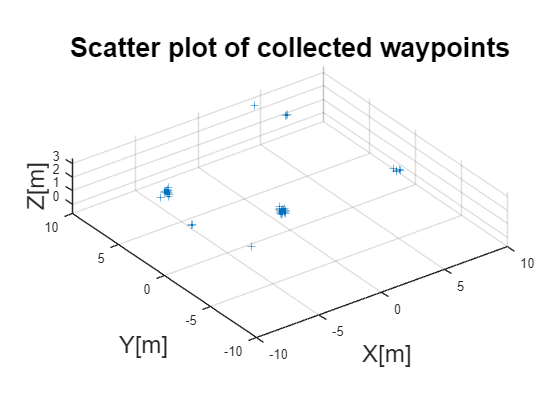

figure;
scatter3(Location(:,1),Location(:,2),Location(:,3),'+');
title('Scatter plot of collected waypoints','FontSize',20);
axis equal;
xlabel('X[m]','FontSize',18);
ylabel('Y[m]','FontSize',18);
zlabel('Z[m]','FontSize',18);
axis([-10 10 -10 10]);
view([-7.2 16.1])

view([-36.3 29.8])

% % Generate sample 3D data (replace this with your actual data)
% 
% data = Location; % 100 points in 3D space
% 
% % Try different values of K
% maxK = 10;
% distortions = zeros(maxK,1);
% silhouette_scores = zeros(maxK,1);
% 
% % Calculate distortions and silhouette scores for different K values
% for k = 1:maxK
%     [idx, centroids] = kmeans(data, k, 'Replicates', 10);
% 
%     % Calculate distortion (Within-cluster sum of squares)
%     distortions(k) = 0;
%     for i = 1:size(data,1)
%         distortions(k) = distortions(k) + ...
%             sum((data(i,:) - centroids(idx(i),:)).^2);
%     end
% 
%     % Calculate silhouette score
%     if k > 1
%         silhouette_scores(k) = mean(silhouette(data, idx));
%     end
% end
% 
% % Plot elbow curve
% figure;
% subplot(2,1,1);
% plot(1:maxK, distortions, 'bo-', 'LineWidth', 2);
% title('Elbow Method');
% xlabel('Number of Clusters (K)');
% ylabel('Distortion');
% grid on;
% 
% % Plot silhouette scores
% subplot(2,1,2);
% plot(2:maxK, silhouette_scores(2:end), 'ro-', 'LineWidth', 2);
% title('Silhouette Analysis');
% xlabel('Number of Clusters (K)');
% ylabel('Silhouette Score');
% grid on;

% 
% % Visualize clusters for optimal K (example with K=3)
% optimal_k = 3; % Replace with your chosen K based on analysis
% [idx, centroids] = kmeans(data, optimal_k, 'Replicates', 10);
% 
% figure;
% scatter3(data(:,1), data(:,2), data(:,3), 50, idx, 'filled');
% hold on;
% scatter3(centroids(:,1), centroids(:,2), centroids(:,3), 200, ...
%     'k', 'filled', 'MarkerEdgeColor', 'w');
% title(['3D Cluster Visualization (K = ' num2str(optimal_k) ')']);
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% grid on;
% % Generate sample 3D data (replace this with your actual data)

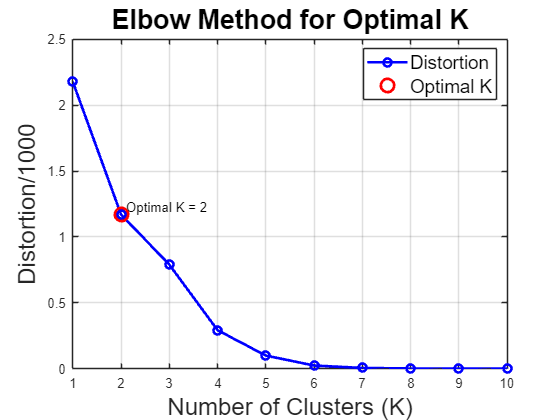

data = Location; % 100 points in 3D space

% Perform K-means clustering
[K,~] = findOptimalK(data,10);

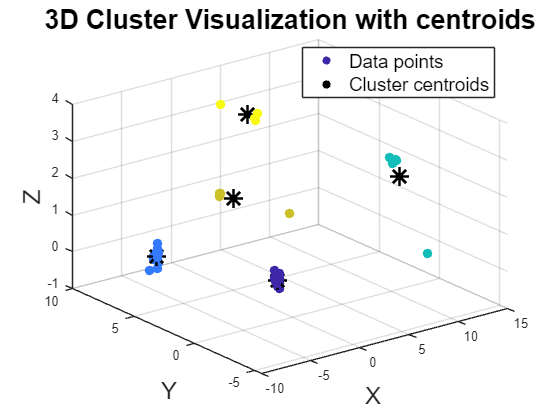

K=5;
[idx, centroids] = kmeans(data, K, 'Replicates', 10);

% Visualize clusters with centroids
figure;
scatter3(data(:,1), data(:,2), data(:,3), 50, idx, 'filled');
hold on;
% Plot cluster means as black stars
scatter3(centroids(:,1), centroids(:,2), centroids(:,3), 200, ...
    'k*', 'LineWidth', 2);
title('3D Cluster Visualization with centroids','FontSize',20);
xlabel('X','FontSize',18);
ylabel('Y','FontSize',18);
zlabel('Z','FontSize',18);
legend('Data points', 'Cluster centroids', 'Location', 'best','FontSize',14);
grid on;

%wpts = [0 0 0.02; 4.53 -3.15 3.35; 4.76 7.12 3.13];
%wpts = [0 0 0.02; 4.53 -3.15 3.35; 4.76 7.12 3.13;-9.37 3.14 0.02];
wpts = [0.66 1.81 0.02;4.76 7.12 3.13; 6.11 -3.37 3.44; -4.01 8.09 0.02; -8.57 -1.11 3.25]

wpts =     0.6600    1.8100    0.0200
    4.7600    7.1200    3.1300
    6.1100   -3.3700    3.4400
   -4.0100    8.0900    0.0200
   -8.5700   -1.1100    3.2500


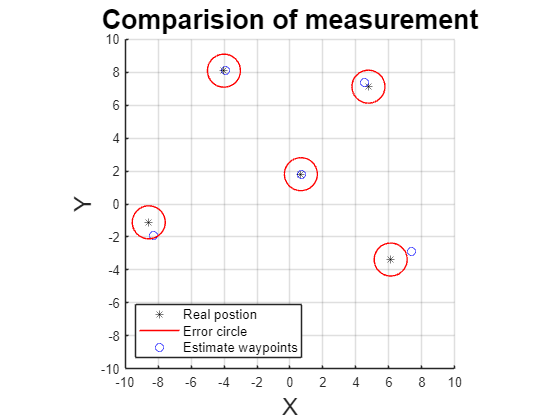


figure; hold on;
for i = 1:height(centroids)
    r = 1;
    xc = wpts(i,1);
    yc = wpts(i,2);
    theta = linspace(0,2*pi,100);
    plot(xc,yc,'k*');
    plot(xc+r*cos(theta),yc+r*sin(theta),'r-');
    plot(centroids(i,1),centroids(i,2),'bo');
end
legend('Real postion','Error circle','Estimate waypoints','fontsize',10,'location','southwest');
xlabel('X','FontSize',18);
ylabel('Y','FontSize',18);
title('Comparision of measurement','FontSize',20)
grid on;
axis equal;
axis([-10 10 -10 10])
xticks([-10:2:10]);
yticks(-10:2:10);